# 参考信号的引入

note3所构建的调节器（Regulator）只能将系统的状态/输出调整到零位，或者说只能对外界扰动进行补偿。

为了将系统的输出调制到特定的参考信号（Reference）上，我们还应当以适当的形式将参考信号引入到闭环。

设被控对象状态空间描述为：$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot x}} = {\mathbf{Ax}} + {\mathbf{B}}u} \\ 
  {y = {\mathbf{Cx}} } 
\end{array}} \right.\]$；

由于我们只能对状态估计和控制命令进行操作，为不失一般性，设参考信号$r$的引入方式为：$\[\left\{ {\begin{array}{*{20}{l}}
{{\bf{\dot \hat x}} = \left( {{\bf{A}} - {\bf{LC}} - {\bf{BK}}} \right){\bf{\hat x}} + {\bf{L}}y + {\bf{M}}r}\\
{u =  - {\bf{K\hat x}} + Nr}
\end{array}} \right.\]$。

下面我们以note3的模型为基础，介绍参数$\mathbf{M}$和$N$的设计方法。

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')
close all
clear;clc

T = 40;
Ts = 1e-3;
stepT = 20;

% Plant
x0 = [0.3 0.1]';
omgn = 2;
A = [0 1; omgn^2 0];
B = [0 1]';
C = [1 0];

% Control Law
K = [5 1];

% State Estimator
L = [7 29]';

## 1) Standard Case

从状态观测器的角度来考察，我们不希望参考信号的引入对状态估计产生影响，考察状态估计的误差为：


$$\[{\bf{\dot \tilde x}} = {\bf{Ax}} + {\bf{B}}\left( { - {\bf{K\hat x}} + Nr} \right) - \left[ {\left( {{\bf{A}} - {\bf{LC}} - {\bf{BK}}} \right){\bf{\hat x}} + {\bf{L}}y + {\bf{M}}r} \right] = \left( {{\bf{A}} - {\bf{LC}}} \right){\bf{\tilde x}} + \left( {{\bf{B}}N - {\bf{M}}} \right)r\]$$


因此，我们只需要令$\mathbf{M} = \mathbf{B}N$就可以避免参考信号对状态估计引入任何扰动。

在这种配置下，估计器的状态空间可以进一步改写为：$\[\left\{ {\begin{array}{*{20}{l}}
{{\bf{\dot \hat x}} = \left( {{\bf{A}} - {\bf{LC}}} \right){\bf{\hat x}} + {\bf{B}}u + {\bf{L}}y}\\
{u =  - {\bf{K\hat x}} + Nr}
\end{array}} \right.\]$。

这就意味着状态观测器的输入与被控对象完全一致。

此时，我们只需要对参考信号的增益$N$进行设计，只需要令$r\rightarrow y$的增益为$1$即可。

闭环系统的状态空间表述为：


$$\[\left\{ \begin{array}{l}
\left[ {\begin{array}{*{20}{c}}
{{\bf{\dot x}}}\\
{{\bf{\dot \tilde x}}}
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
{{\bf{A}} - {\bf{BK}}}&{{\bf{BK}}}\\
{\bf{0}}&{{\bf{A}} - {\bf{LC}}}
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{\bf{x}}\\
{{\bf{\tilde x}}}
\end{array}} \right] + \left[ {\begin{array}{*{20}{c}}
{\bf{B}}\\
{\bf{0}}
\end{array}} \right]Nr\\
y = \left[ {\begin{array}{*{20}{c}}
{\bf{C}}&0
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{\bf{x}}\\
{{\bf{\tilde x}}}
\end{array}} \right]
\end{array} \right.\]$$


根据$r\rightarrow y$的增益为$1$可解得：$ N =  - {\left\{ {\left[ {\begin{array}{*{20}{c}}
{\bf{C}}&0
\end{array}} \right]{{\left[ {\begin{array}{*{20}{c}}
{{\bf{A}} - {\bf{BK}}}&{{\bf{BK}}}\\
{\bf{0}}&{{\bf{A}} - {\bf{LC}}}
\end{array}} \right]}^{ - 1}}\left[ {\begin{array}{*{20}{c}}
{\bf{B}}\\
{\bf{0}}
\end{array}} \right]} \right\}^{ - 1}}$

% N --> R, avoid conflict
R = -[C 0 0]/[A-B*K B*K; zeros(2) A-L*C]*[B;0;0];
R = 1/R;

## 2) Error-Control Case

如果令$N=0$，$\mathbf{M}=-\mathbf{L}$，即可得到基于误差控制的参考信号引入方式，这是经典控制中的常用方式。

设系统的开环传递函数为$H_{open}$，那么由参考信号到系统输出的传递函数为：$H_{close}=\frac{H_{open}}{1+H_{open}} \rightarrow 1$。

显然，在闭环传递函数的约束下被控对象的输出会跟随输入，因此不需要额外地设计参数。

## 3) General Case

更一般地，我们可以通过人为设计参数$\mathbf{M}$和$N$ 来改变系统的零点，考察由$r\rightarrow u
$的零点满足（这里关注$r$，可以暂时令$y=0$）：


$$\[\left| {\begin{array}{*{20}{c}}
{{\bf{I}}s - \left( {{\bf{A}} - {\bf{BK}} - {\bf{LC}}} \right)}&{ - {\bf{M}}}\\
{ - {\bf{K}}}&N
\end{array}} \right| = 0 \Rightarrow \left| {{\bf{I}}s - {\bf{A}} + {\bf{BK}} + {\bf{LC}} - \frac{{\bf{M}}}{N}{\bf{K}}} \right| = \left| {{\bf{I}}s - {\bf{A}} + {\bf{BK}} + {\bf{LC}} - {\bf{\bar MK}}} \right| = 0\]$$


$r\rightarrow u
$也是$r\rightarrow y$的零点，除非存在极点与其相消。

因此，我们可以首先根据零点对$\[{\bf{\bar M}} = \frac{{\bf{M}}}{N}\]$进行设计，再根据$r\rightarrow y$的增益为$1$计算得$N$。

例如，我们希望在$-7.07\pm7.07j$处引入一个零点，可以利用MATLAB的符号计算获得：

Mbar = sym('m',[2 1]);
p1 = charpoly(A-B*K-L*C+Mbar*K);
p2 = poly([7+7.07j 7-7.07j]);
p = solve(p1 == p2);
Mb = double([p.m1 p.m2]');
fprintf('Mbar = [ %5.3f, %5.3f ]''\n',Mb)

Mbar = [ 3.835, 2.824 ]'


考察$r\rightarrow y$的增益为：


$$\[\left\{ {\begin{array}{*{20}{l}}
{\left[ {\begin{array}{*{20}{c}}
{{\bf{\dot x}}}\\
{{\bf{\dot \tilde x}}}
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
{{\bf{A}} - {\bf{BK}}}&{{\bf{BK}}}\\
{\bf{0}}&{{\bf{A}} - {\bf{LC}}}
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{\bf{x}}\\
{{\bf{\tilde x}}}
\end{array}} \right] + \left[ {\begin{array}{*{20}{c}}
{\bf{B}}\\
{{\bf{B}} - {\bf{\bar M}}}
\end{array}} \right]Nr}\\
{y = \left[ {\begin{array}{*{20}{c}}
{\bf{C}}&0
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{\bf{x}}\\
{{\bf{\tilde x}}}
\end{array}} \right]}
\end{array}} \right. \Rightarrow  - \left[ {\begin{array}{*{20}{c}}
{\bf{C}}&0
\end{array}} \right]{\left[ {\begin{array}{*{20}{c}}
{{\bf{A}} - {\bf{BK}}}&{{\bf{BK}}}\\
{\bf{0}}&{{\bf{A}} - {\bf{LC}}}
\end{array}} \right]^{ - 1}}\left[ {\begin{array}{*{20}{c}}
{\bf{B}}\\
{{\bf{B}} - {\bf{\bar M}}}
\end{array}} \right]N = 1\]$$


则有：$\[N =  - {\left\{ {\left[ {\begin{array}{*{20}{c}}
{\bf{C}}&0
\end{array}} \right]{{\left[ {\begin{array}{*{20}{c}}
{{\bf{A}} - {\bf{BK}}}&{{\bf{BK}}}\\
{\bf{0}}&{{\bf{A}} - {\bf{LC}}}
\end{array}} \right]}^{ - 1}}\left[ {\begin{array}{*{20}{c}}
{\bf{B}}\\
{{\bf{B}} - {\bf{\bar M}}}
\end{array}} \right]} \right\}^{ - 1}}\]$

N = -[C 0 0]/[A-B*K B*K; zeros(2) A-L*C]*[B;B-Mb];
N = 1/N;
M = N*Mb;

## 三种方法的对比

我们给系统一定的初始状态，并在其收敛后加入单位阶跃信号（20 s处），观察系统的响应。

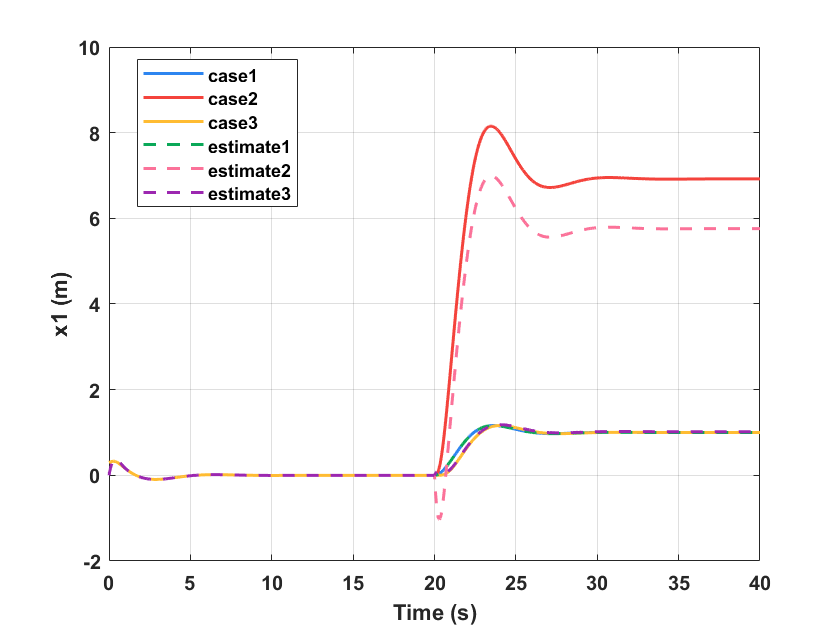

sim('model3_ReferenceInput.slx')

figure
plot(t,[x1(:,1) x2(:,1) x3(:,1)])
hold on
grid on
plot(t,[xm1(:,1) xm2(:,1) xm3(:,1)],'--')
legend('case1','case2','case3',...
    'estimate1','estimate2','estimate3',...
    'Location','best')
xlabel('Time (s)')
ylabel('x1 (m)')

上面这个图是三种方式引入参考信号时系统的输出（位移，也就是第一个状态变量），可以看出三种方式都能够使系统的输出跟随参考信号做出一定的响应。不同的是，case1和case3的系统输出能够跟随参考信号，而case2却有明显的稳态误差，这是因为我们假设了闭环传递函数满足$H_{close}=\frac{H_{open}}{1+H_{open}} \rightarrow 1$，这个条件的要想得到满足，开环传递函数的直流增益必须足够大，这暗示我们在控制中引入积分器。实际上，对于真实的系统，设计值与真实值难免存在偏差，都会导致输出与预期存在误差，这种误差可以通过使用积分器来增加系统的鲁棒性抑制或消除，我们将在以后进行讨论。

由于本例中零点的选择是任意的，所以case3的动态过程与case1未见明显差别，零点的设计在动态过程要求高的情况下更加适用。

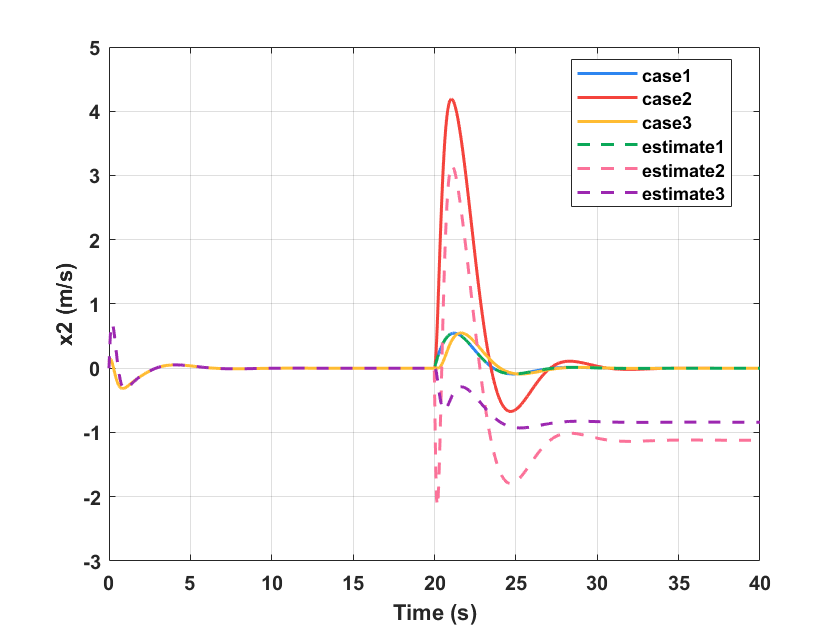

figure
plot(t,[x1(:,2) x2(:,2) x3(:,2)])
hold on
grid on
plot(t,[xm1(:,2) xm2(:,2) xm3(:,2)],'--')
legend('case1','case2','case3',...
    'estimate1','estimate2','estimate3',...
    'Location','best')
xlabel('Time (s)')
ylabel('x2 (m/s)')

我们不妨再对比一下上图所示的速度状态变量，这时，case2和case3都产生的稳态误差，说明参考信号的引入对状态估计产生了扰动（case1推导中的$\mathbf{M} = \mathbf{B}N$未能得到满足）。其次，注意到阶跃信号输入的时刻，case1的状态估计值紧随真实状态，不受参考信号的扰动而出现误差或动态响应，而case2和case3都有大约7s左右的收敛过程，再次说明参考信号对这两种设计的状态估计存在影响。

综合对比三种设计方法，我们可以初步得到以下认识：

- case1所示的方法既能够引入参考信号，又避免对状态估计产生影响，且参数易于设计，因而应用较广；

- case2的方法与经典控制相同，常用于某些传感器测量值本身就是误差信号的情况，其稳态误差应当予以重视；

- case3的设计方法最为灵活，对于动态响应要求较高的系统可以对零点进行补充设计，适用范围最广；

- case2和case3的状态估计会受到参考信号的控制，因此如果需要对系统的真实状态进行估计，还需要另外增加状态估计器。